## Active Suspension System

Complementary example for Part 3 of the workshop - **Robust Control of Active Suspension **section.

Once we obtain a simplified model of the plant, we can design a feedback controller K, that will take in some measurements, which we will call v, and produce the controlled variables u. For our system, we have one controlled variable, which is the hydraulic force being requested from the actuator $f_s$, and we will use two measurements: vehicle body acceleration $a_b$, and suspension deflection $s_d$.

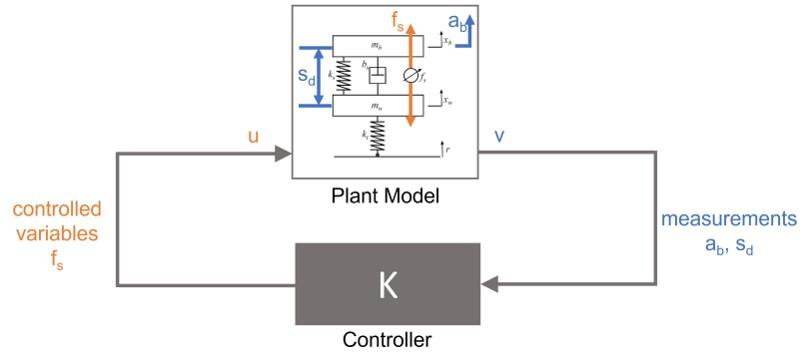

So this defines our feedback control problem. Now we will get into how we design the controller for it.

We will start with $H_{\infty }$ synthesis. To understand conceptually what $H_{\infty }$, and eventually $\mu$ systhesis is doing, we need to expand the block diagram. In addition to the controller input, we have external inputs into the system that come from sources like disturbances and noise, and even reference signals. We will call this w. And there are other outputs that we need to look at as well. This are the error signals that give us a sense of how well the system is performing. We will call these z.

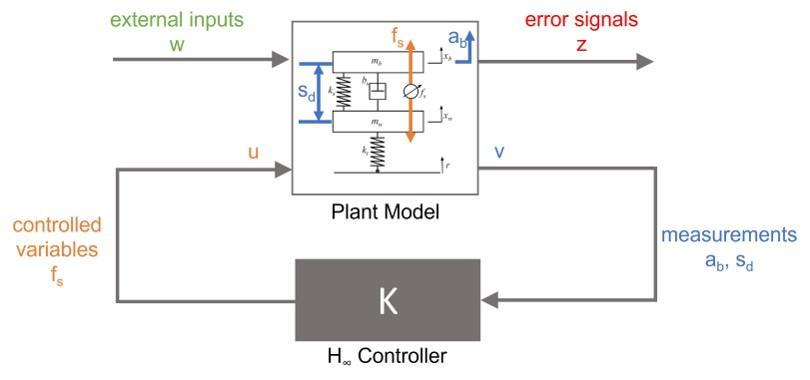

Lets say that our plant has a single external input that we care about, that is the disturbance that comes in when we hit a bump on the road. And there are three error signals that we want to use to define performance: the body acceleration, the suspension deflection, and the requested actuator force.

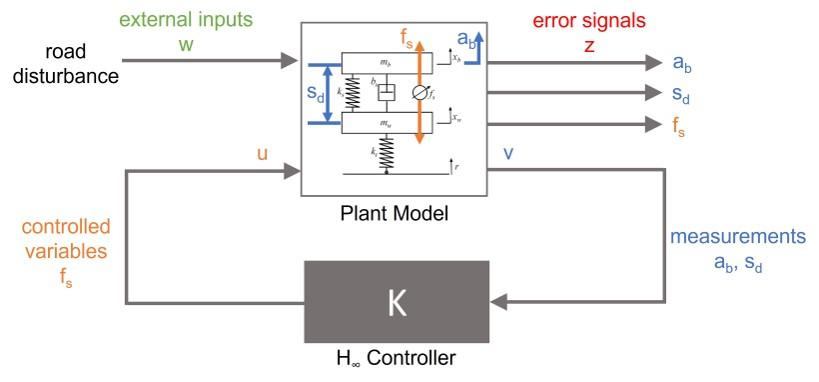

SO, here is the whole design problem in a nutshell: We want a controller that minimizes the error signals when a disturbance enters the system. The goal of our active suspension controller is to drive the actuator such that the amplification of any road disturbance is minimized, and in the process, uses the least amount of actuator force possible. This is exactly what $H_{\infty }$ synthesis is doing for us. It is an optimization process that calculates the controller that minimizes the gain between w and z.

However, as a designer, you might not want each signal to be treated equally in this optimization problem, therefore we can manipulate the signals within the model by adding weighting factors to w and z to set the importance of individual signals. For example, we may lower the actuator weighting factor is we are not as concerned about actuator energy as we are about body acceleration. Or we may increase the weight if we want to drive the actuator less because we are more concerned about extending its life. 

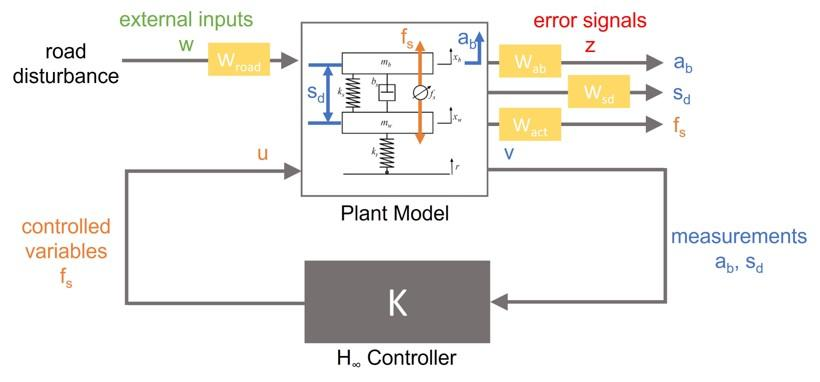

We may develop more than one controller, each with a different set of weights, and then allow the user to switch between different active suspension modes like performance and comfort, or a balance between the two.

## Quarter Car Suspension Model

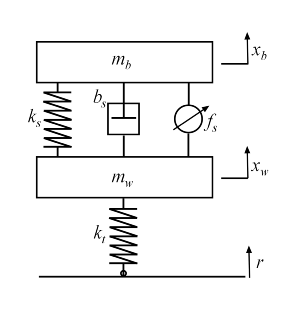

clear, clf
% Define the physical parameters
mb = 300;       % kg
mw = 60;        % kg
bs = 1000;      % N/m/s
ks = 16000;     % N/m
kt = 190000;    % N/m

% State matrices
A = [ 0 1 0 0; [-ks -bs ks bs]/mb ; ...
      0 0 0 1; [ks bs -ks-kt -bs]/mw];
B = [ 0 0; 0 1e3/mb ; 0 0 ; [kt -1e3]/mw];
C = [1 0 0 0; 1 0 -1 0; A(2,:)];
D = [0 0; 0 0; B(2,:)];

qcar = ss(A,B,C,D);
qcar.StateName = {'body travel (m)';'body vel (m/s)';...
          'wheel travel (m)';'wheel vel (m/s)'};
qcar.InputName = {'r';'fs'};
qcar.OutputName = {'xb';'sd';'ab'};

Note that for the moment, we will assume that this model is perfect, and there are no uncertainties in our dynamics. We will come back to this assumption in just a bit.

## Actuator Model

% Nominal actuator model
ActNom = tf(1,[1/60 1]);
ActNom.InputName = 'u';
ActNom.OutputName = 'fs';

Another thing to note is that we are modeling the actuator as a first order system. This means that the controller requests a force u, but the actual force that the actuator generates (fs) depends on its dynamics.

## Design Setup

To continue the rest of the design setup, we set individual weighting functions for each of the signals.

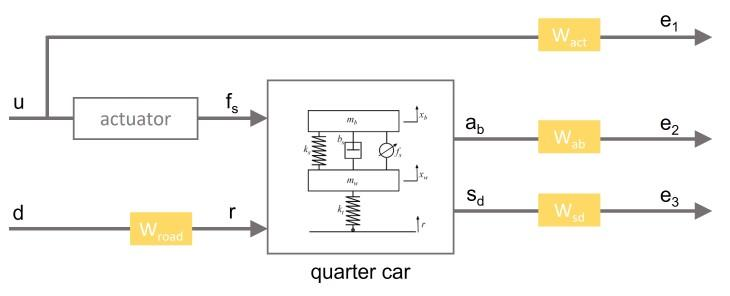

% Weights
Wroad = ss(0.07);  Wroad.u = 'd';   Wroad.y = 'r';
Wact = 0.8*tf([1 50],[1 500]);  Wact.u = 'u';  Wact.y = 'e1';

HandlingTarget = 0.04 * tf([1/8 1],[1/80 1]);
ComfortTarget = 0.4 * tf([1/0.45 1],[1/150 1]);

% Three design points
beta = reshape([0.01 0.5 0.99],[1 1 3]);
Wsd = beta / HandlingTarget;
Wsd.u = 'sd';  Wsd.y = 'e3';
Wab = (1-beta) / ComfortTarget;
Wab.u = 'ab';  Wab.y = 'e2';

We will solve the problem for three different controllers, one for each of the three different sets of weights.

## Connect the parts together into a single open loop model

sdmeas  = sumblk('y1 = sd');
abmeas = sumblk('y2 = ab');
ICinputs = {'d';'u'};
ICoutputs = {'e1';'e2';'e3';'y1';'y2'};
qcaric = connect(qcar(2:3,:),ActNom,Wroad,Wact,Wab,Wsd,...
                 sdmeas,abmeas,ICinputs,ICoutputs);

## Nominal H-infinity Design

Use [`hinfsyn`](https://www.mathworks.com/help/releases/R2022b/robust/ref/lti.hinfsyn.html) to compute an $H_\infty$ controller for each value of the blending factor $\beta$.

ncont = 1; % one control signal, u
nmeas = 2; % two measurement signals, sd and ab
K = ss(zeros(ncont,nmeas,3));
gamma = zeros(3,1);
for i=1:3
   [K(:,:,i),~,gamma(i)] = hinfsyn(qcaric(:,:,i),nmeas,ncont);
end

## Build the closed loop system

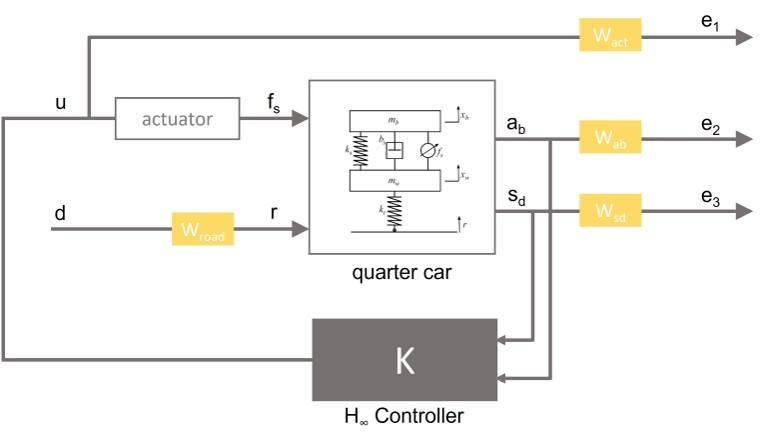

% Closed-loop models
K.u = {'sd','ab'};  K.y = 'u';
CL = connect(qcar,ActNom,K,'r',{'xb';'sd';'ab'});

## Time domain evaluation

To further evaluate the three designs, perform time-domain simulations using a road disturbance signal $r(t)$ representing a 5 cm. road bump.

% Road disturbance
t = 0:0.0025:1;
roaddist = zeros(size(t));
roaddist(1:101) = 0.025*(1-cos(8*pi*t(1:101)));

% Simulate
p1 = lsim(qcar(:,1),roaddist,t);          % Open loop
y1 = lsim(CL(1:3,1,1),roaddist,t);        % Comfort
y2 = lsim(CL(1:3,1,2),roaddist,t);        % Balanced
y3 = lsim(CL(1:3,1,3),roaddist,t);        % Handling

% Plot results
plot(t,p1(:,1),'b',t,y1(:,1),'r.',t,y2(:,1),'m.',t,y3(:,1),'k.',t,roaddist,'g'), grid
title('Body travel'), ylabel('x_b (m)')
legend('Open-loop','Comfort','Balanced','Handling','Road Disturbance','location','NorthEast')

## Uncertain Actuator Model

Wunc = makeweight(0.80,15,3);
unc = ultidyn('unc',[1 1],'SampleStateDim',5);
ActUnc = ActNom*(1 + Wunc*unc);
ActUnc.InputName = 'u';
ActUnc.OutputName = 'fs';

## Rebuild the open loop model with uncertain actuator

qcaric = connect(qcar(2:3,:),ActUnc,Wroad,Wact,Wab,Wsd,...
                 sdmeas,abmeas,ICinputs,ICoutputs);

% Set randomization parameters for visualizing uncertain systems
rng('default'), nsamp = 100; clf

% Road disturbance
t = 0:0.0025:1.5;
roaddist = zeros(size(t));
roaddist(1:101) = 0.025*(1-cos(8*pi*t(1:101)));

% For simplicity we will look only at the "balanced" controller
CLU = connect(qcar,ActUnc,K(:,:,2),'r',{'xb';'sd';'ab'});

% Simulate
lsim(usample(CLU,nsamp),'b',roaddist,t);
title('Nominal "balanced" design')
legend('Perturbed','location','SouthEast')

Most of the actuator combinations appear to be stable and produce a reasonable response, however, some variations produce an unstable response, so the $H_{\infty }$ controller we designed is NOT a great solution if the actuator dynamics can really vary as much as we modeled. We could go back and tweak the weights on the different signals and try to come up with a controller that is stable across all these variations, but if we already have a model of our uncertain system, why not just develop a controller that takes those uncertainties into account from the start. **THIS is what **$\mu$** synthesis does**.

## Robust Mu Design

$\mu$ synthesis is an extension of $H_{\infty }$ in the sense that it is still solving the same problem, except that it tries to minimize the worst case gain across the entire uncertainty space.

[Krob,rpMU] = musyn(qcaric(:,:,2),nmeas,ncont);

$\mu$ synthesis is running and iterative process, where essentially it run and  $H_{\infty }$ synthesis at each step to find a nominal controller, and checking its robustness. Then it scales the problem based on the uncertainty in the system and runs another $H_{\infty }$ synthesis, and again, and again, until the robust performance stops improving. The robust performance s the Peak MU value, and in general, the lower the number, the more robust the system.

## Compare the performance of the two controllers

clf
% Balanced H infinity controller
CLU = connect(qcar,ActUnc,K(:,:,2),'r',{'xb';'sd';'ab'});
lsim(usample(CLU,nsamp),'b',roaddist,t);
hold all

% Balanced robust controller
Krob.u = {'sd','ab'};
Krob.y = 'u';
CLU = connect(qcar,ActUnc,Krob,'r',{'xb';'sd';'ab'});
lsim(usample(CLU,nsamp),'r',roaddist,t);
title('"Balanced" design')
legend({'H infinity','Mu synthesis'},'location','SouthEast')
hold off